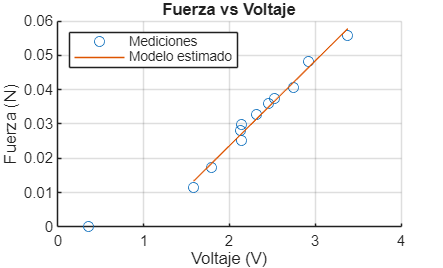

T = readtable('Calibración.xlsx');
Fuerza = T.Var2(1:12);
Voltaje = T.Var1(1:12);
p = polyfit(Voltaje(1:end-1), Fuerza(1:end-1), 1);
y_fit = polyval(p, Voltaje(1:end-1));
figure;
scatter(Voltaje, Fuerza); grid on;
hold on
plot(Voltaje(1:end-1), y_fit)
xlabel('Voltaje (V)');
ylabel('Fuerza (N)');
legend('Mediciones', 'Modelo estimado', 'Location', "northwest");
title('Fuerza vs Voltaje');

lines = readlines("Fricción.log");

% Inicializar vector
angles = [];

% Expresión regular para extraer el número después de "Angle:"
for i = 1:length(lines)
    match = regexp(lines(i), 'Angle:\s*(-?\d+\.?\d*)', 'tokens');
    if ~isempty(match)
        angles(end+1) = str2double(match{1}{1});
    end
end

firstIndex = find(abs(angles - angles(1)) > 0.35, 1, 'first') + 1;
angles = angles - angles(end);
angles = angles(firstIndex:end);
t = linspace(0,0.01*length(angles),length(angles)); 

Ts = median(diff(t));               
t_disc = t(1):Ts:t(end);    
angle_disc = interp1(t, angles, t_disc);

% Estimar parámetros desde picos medidos 
[pks, locs] = findpeaks(angle_disc, t_disc);
A = pks(1:4);   % Picos
Td = locs(2)-locs(1);     % Periodo entre picos en s

delta_vals = log(A(1:end-1) ./ A(2:end));
delta = mean(delta_vals);
zeta = delta/sqrt((2*pi)^2 + delta^2);
omega_d = 2*pi/Td;
omega_n = omega_d/sqrt(1 - zeta^2);

fprintf('Parámetros estimados:\n');

Parámetros estimados:


fprintf('zeta     = %.5f\n', zeta);

zeta     = 0.04869


fprintf('omega_n  = %.5f rad/s\n', omega_n);

omega_n  = 8.38187 rad/s


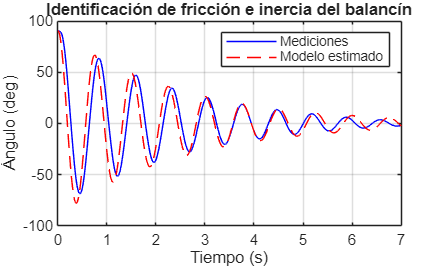


% Construir modelo en espacio de estados 
A = [0      1;
    -omega_n^2  -2*zeta*omega_n];
B = [0; 0];     
C = [1 0];
D = 0;

sys = ss(A, B, C, D);  % Modelo de segundo orden
% Simulación con condiciones iniciales
angle0 = angle_disc(1);
x0 = [angle0; 0];      % [ángulo inicial; velocidad inicial]
u = zeros(size(t_disc));
y_sim = lsim(sys, u, t_disc, x0);

% Graficar comparación 
figure;
plot(t_disc, angle_disc, 'b'); hold on;
plot(t_disc, y_sim, 'r--');
xlabel('Tiempo (s)');
ylabel('Ángulo (deg)');
xlim([0, 7])
legend('Mediciones', 'Modelo estimado');
title('Identificación de fricción e inercia del balancín');
grid on;

WL = 0.04;
WR = 0.02;
a = 0.120;
b = 0.06253;
c = 0.02605;
Tot_M = WL*b-WR*c;
J = Tot_M/omega_n^2;        % Momento de inercia (kg·m^2)
B = J*2*zeta*omega_n*4.3;       % Fricción Viscosa (kg·m^2/s)
BJ = B/J;
TotJ = Tot_M/J;
aJ = a/J;
MotC = 0.008;              % Constante motor (N/V)
deadZ = 0.15;

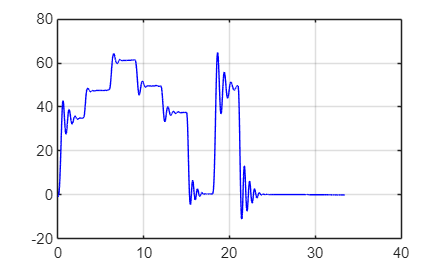

% Leer todas las líneas del archivo
lines = readlines('Motor.log');

% Expresión regular para buscar: t: xxx ms, ángulo: yyy.yy
expr = 't:\s*(\d+)\s*ms,\s*ángulo:\s*([-+]?[0-9]*\.?[0-9]+)';

% Aplicar expresión a cada línea
matches = regexp(lines, expr, 'tokens');

% Filtrar líneas válidas: deben tener exactamente 2 datos
matches = matches(~cellfun(@isempty, matches));  % Eliminar vacíos
matches = matches(cellfun(@(x) numel(x{1}) == 2, matches));  % Solo las válidas

% Convertir a arrays numéricos
t_i = cellfun(@(x) str2double(x{1}{1}), matches) / 1000;   % Tiempo en segundos
angle_i = cellfun(@(x) str2double(x{1}{2}), matches); % Ángulo en grados
idx_ini = find(t_i >= 2.5, 1);  % Primer índice con t ≥ 2.5
angle_i = angle_i(idx_ini:end)-angle_i(end);
t_i = t_i(idx_ini:end)-t_i(idx_ini)*ones(length(angle_i),1);    

% Graficar para verificar
figure;
plot(t_i, angle_i, 'b'); grid on;
hold on

plot(out.angulo.time, rad2deg(out.angulo.signals.values), "r--")

Unable to resolve the name 'out.angulo.time'.

xlabel('Tiempo (s)');
ylabel('Ángulo (deg)');
xlim([0,30])
legend('Mediciones', 'Modelo estimado', "Location", "southwest");
title('Ángulo vs Tiempo');

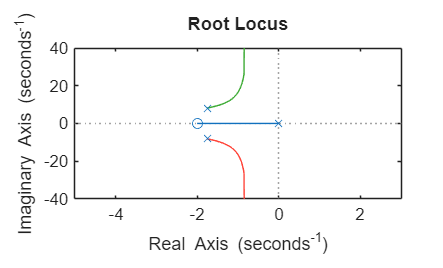

K_Des = 2.3360

Pol_Des =   -1.2142 +12.0715i
  -1.2142 -12.0715i
  -1.0811 + 0.0000i


Alin = [0      1;
        -70.2558  -3.5095];
Blin = [0; 34.0600];     
Clin = [1 0];
Dlin = 0;
linmod = ss(Alin,Blin,Clin,Dlin);
G_lin = tf(linmod);
ts_Des = 3.7;
zeta_Des = 1;
wn_Des = 4/ts_Des;
Ti_Des = 0.5;
I_Des = tf([Ti_Des 1],[Ti_Des 0])*G_lin;
figure
[K_Des, Pol_Des] = rlocfind(I_Des, -wn_Des*zeta_Des)

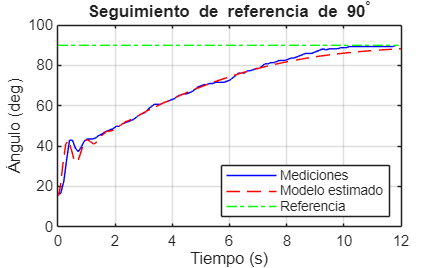

% Cargar archivo completo como texto
filename = 'Controladores_Def.log'; % <-- cambia por el nombre de tu archivo
lines = readlines(filename);

% Filtrar solo las líneas del PID
pid_lines = lines(contains(lines, 'PID -'));

% Inicializar vectores
t = zeros(length(pid_lines), 1);
angulo = zeros(length(pid_lines), 1);
referencia = zeros(length(pid_lines), 1);
error = zeros(length(pid_lines), 1);
senal = zeros(length(pid_lines), 1);

% Expresión regular para extraer datos
expr = 'PID - t: (\d+) Angulo: ([\d\.]+) Referencia: ([\d\.]+) Error: ([\d\.]+) Señal: ([\d\.]+)';

for i = 1:length(pid_lines)
    tokens = regexp(pid_lines(i), expr, 'tokens');
    if ~isempty(tokens)
        valores = str2double(tokens{1});
        t(i) = valores(1)/1000;
        angulo(i) = valores(2);
        referencia(i) = valores(3);
        error(i) = valores(4);
        senal(i) = valores(5);
    end
end

idx_corte = find(senal == 0.00, 1);

% Si se encuentra, cortar todos los datos desde ahí
if ~isempty(idx_corte)
    t = t(1:idx_corte-1);
    angulo = angulo(1:idx_corte-1);
    referencia = referencia(1:idx_corte-1);
    error = error(1:idx_corte-1);
    senal = senal(1:idx_corte-1);
end

% Detectar el primer punto donde la señal simulada varía
angle_sim = out.angulo.signals.values;
error_sim = out.error.signals.values;
senal_sim = out.voltaje.signals.values;
reference = out.reference.signals.values;
t_sim = out.voltaje.time;
delta_min = 1e-3; % tolerancia para detectar el cambio (ajustable)
senal_ref = senal_sim(1);
idx_ini = find(abs(senal_sim - senal_ref) > delta_min, 1);

% Recorte por tiempo: durará igual que la señal real
duracion_real = t(end) - t(1);
tiempo_inicio = t_sim(idx_ini);
tiempo_final = tiempo_inicio + duracion_real;

% Buscar índices para recorte completo
idx_fin = find(t_sim >= tiempo_final, 1);

% Si no lo encuentra, usar el final del vector
if isempty(idx_fin)
    idx_fin = length(t_sim);
end

% Recortar señal y tiempo simulados
angle_sim = angle_sim(idx_ini:idx_fin);
error_sim = error_sim(idx_ini:idx_fin);
reference = reference(idx_ini:idx_fin);
senal_sim = senal_sim(idx_ini:idx_fin);
t_sim = t_sim(idx_ini:idx_fin)-tiempo_inicio;

figure;
plot(t, rad2deg(angulo), 'b'); grid on; hold on;
plot(t_sim, rad2deg(angle_sim), "r --")
plot(t, rad2deg(referencia), "g -.")
xlabel('Tiempo (s)');
ylabel('Ángulo (deg)');
legend("Mediciones", 'Modelo estimado', "Referencia","Location", "southeast");
title('Seguimiento de referencia de 90^\circ');

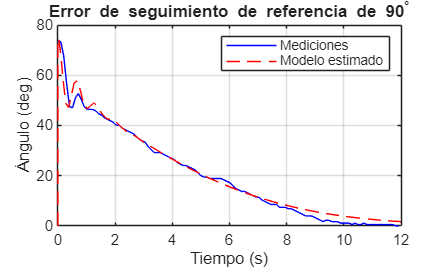


figure;
plot(t, rad2deg(error), 'b'); grid on; hold on;
plot(t_sim, rad2deg(error_sim), "r --")
xlabel('Tiempo (s)');
ylabel('Ángulo (deg)');
legend("Mediciones", 'Modelo estimado');
title('Error de seguimiento de referencia de 90^\circ');

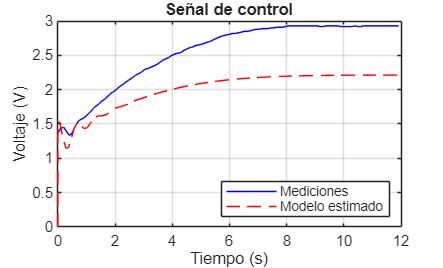


figure;
plot(t, senal, 'b'); grid on; hold on;
plot(t_sim, senal_sim, "r --")
legend('Mediciones', 'Modelo estimado', "Location", "southeast");
xlabel('Tiempo (s)');
ylabel('Voltaje (V)');
title('Señal de control');